# 初始化

clear; clc; close all;

## 创建机器人模型（Modified DH参数）

L_M(1) = Link('revolute', 'd', 0.12202, 'a', 0, 'alpha', 0, 'modified');
L_M(2) = Link('revolute', 'd', 0, 'a', 0.1, 'alpha', -pi/2, 'modified', 'offset', -pi/2);
L_M(3) = Link('revolute', 'd', 0, 'a', 0.25, 'alpha', 0, 'modified', 'offset', pi);
L_M(4) = Link('revolute', 'd', 0.187+0.063, 'a', 0, 'alpha', pi/2, 'modified');
L_M(5) = Link('revolute', 'd', 0, 'a', 0, 'alpha', -pi/2, 'modified');
L_M(6) = Link('revolute', 'd', 0.0595, 'a', 0, 'alpha', pi/2, 'modified');
EpsonC3_M = SerialLink(L_M, 'name', 'EpsonC3_M', 'base', transl(0, 0, 0.198));

## 定义起始和目标关节角度

q0 = [0 0 0 0 0 0];                         % 起始关节角
qf = [pi/6 -pi/4 pi/3 -pi/6 pi/4 pi/2];     % 目标关节角
n = 6;                                      % 关节数

## 轨迹规划参数

t_total = 5.0;          % 总运动时间（秒）
dt = 0.01;              % 时间步长
t = 0:dt:t_total;       % 时间向量
N = length(t);          % 轨迹点数量

## 1. 三次多项式轨迹规划

q_cubic = zeros(N, n);
dq_cubic = zeros(N, n);
ddq_cubic = zeros(N, n);

for i = 1:n
    % 计算三次多项式系数
    a0 = q0(i);
    a1 = 0;  % 初始速度为0
    a2 = 3/(t_total^2) * (qf(i) - q0(i));
    a3 = -2/(t_total^3) * (qf(i) - q0(i));
    
    % 计算轨迹
    for j = 1:N
        t_curr = t(j);
        q_cubic(j,i) = a0 + a1*t_curr + a2*t_curr^2 + a3*t_curr^3;
        dq_cubic(j,i) = a1 + 2*a2*t_curr + 3*a3*t_curr^2;
        ddq_cubic(j,i) = 2*a2 + 6*a3*t_curr;
    end
end

## 2. 五次多项式轨迹规划

q_quintic = zeros(N, n);
dq_quintic = zeros(N, n);
ddq_quintic = zeros(N, n);

for i = 1:n
    % 计算五次多项式系数
    a0 = q0(i);
    a1 = 0;  % 初始速度为0
    a2 = 0;  % 初始加速度为0
    a3 = 10/(t_total^3) * (qf(i) - q0(i));
    a4 = -15/(t_total^4) * (qf(i) - q0(i));
    a5 = 6/(t_total^5) * (qf(i) - q0(i));
    
    % 计算轨迹
    for j = 1:N
        t_curr = t(j);
        q_quintic(j,i) = a0 + a1*t_curr + a2*t_curr^2 + a3*t_curr^3 + ...
                         a4*t_curr^4 + a5*t_curr^5;
        dq_quintic(j,i) = a1 + 2*a2*t_curr + 3*a3*t_curr^2 + ...
                         4*a4*t_curr^3 + 5*a5*t_curr^4;
        ddq_quintic(j,i) = 2*a2 + 6*a3*t_curr + 12*a4*t_curr^2 + 20*a5*t_curr^3;
    end
end

## 3. S曲线（梯形速度曲线）轨迹规划

S曲线由抛物线段（二次函数）和直线段组成 方程推导： 1. 匀加速段时间t1=1.5s，匀速段时间t_total-2*t1=2s，匀减速段时间1.5s 2. 设加速度a，则最大速度为1.5a 3. 总位移：qf-q0=2*(1/2*t1*t1*a)+(t_total-2*t1)*t1*a=(t_total-t1)*t1*a

q_s_curve = zeros(N, n);
dq_s_curve = zeros(N, n);
ddq_s_curve = zeros(N, n);

for i = 1:n
    % 计算加速度a
    t1 = 1.5;
    a=(qf(i)-q0(i)) / ( (t_total-t1)*t1 );
    
    % 计算轨迹
    for j = 1:N
        t_curr = t(j);
        if t_curr <= t1
            % 匀加速段
            q_s_curve(j,i) = 1/2*a*t_curr^2;
            dq_s_curve(j,i) = a*t_curr;
            ddq_s_curve(j,i) = a;
        elseif (t1 < t_curr) && (t_curr <= (t_total - t1))
            % 匀速段
            q_s_curve(j,i) = 1/2*a*t1^2 + a*t1*(t_curr - t1);
            dq_s_curve(j,i) = a*t1;
            ddq_s_curve(j,i) = 0;
        elseif ((t_total - t1) < t_curr) && (t_curr <= t_total)
            % 匀减速段
            q_s_curve(j,i) = 1/2*a*t1^2 + a*t1*(t_curr - t1) - 1/2*a*(t_curr - (t_total - t1))^2;
            dq_s_curve(j,i) = -a*(t_curr - t_total);
            ddq_s_curve(j,i) = -a;
        end
    end
end

## 计算机器人末端轨迹

初始化存储数组

pos_cubic = zeros(N, 3);
vel_cubic = zeros(N, 3);
pos_quintic = zeros(N, 3);
vel_quintic = zeros(N, 3);
pos_s_curve = zeros(N, 3);
vel_s_curve = zeros(N, 3);

% 计算每种方法的末端轨迹
for j = 1:N
    % 三次多项式
    T_cubic = EpsonC3_M.fkine(q_cubic(j,:));
    pos_cubic(j,:) = transl(T_cubic)';
    J_cubic = EpsonC3_M.jacob0(q_cubic(j,:));
    vel_cubic(j,:) = J_cubic(1:3,:) * dq_cubic(j,:)';
    
    % 五次多项式
    T_quintic = EpsonC3_M.fkine(q_quintic(j,:));
    pos_quintic(j,:) = transl(T_quintic)';
    J_quintic = EpsonC3_M.jacob0(q_quintic(j,:));
    vel_quintic(j,:) = J_quintic(1:3,:) * dq_quintic(j,:)';
    
    % S曲线
    T_s_curve = EpsonC3_M.fkine(q_s_curve(j,:));
    pos_s_curve(j,:) = transl(T_s_curve)';
    J_s_curve = EpsonC3_M.jacob0(q_s_curve(j,:));
    vel_s_curve(j,:) = J_s_curve(1:3,:) * dq_s_curve(j,:)';
end

% 计算末端加速度（通过速度差分）
acc_cubic = diff(vel_cubic)/dt;
acc_cubic = [acc_cubic; acc_cubic(end,:)];
acc_quintic = diff(vel_quintic)/dt;
acc_quintic = [acc_quintic; acc_quintic(end,:)];
acc_s_curve = diff(vel_s_curve)/dt;
acc_s_curve = [acc_s_curve; acc_s_curve(end,:)];

## 绘制对比图

1. 关节空间轨迹对比

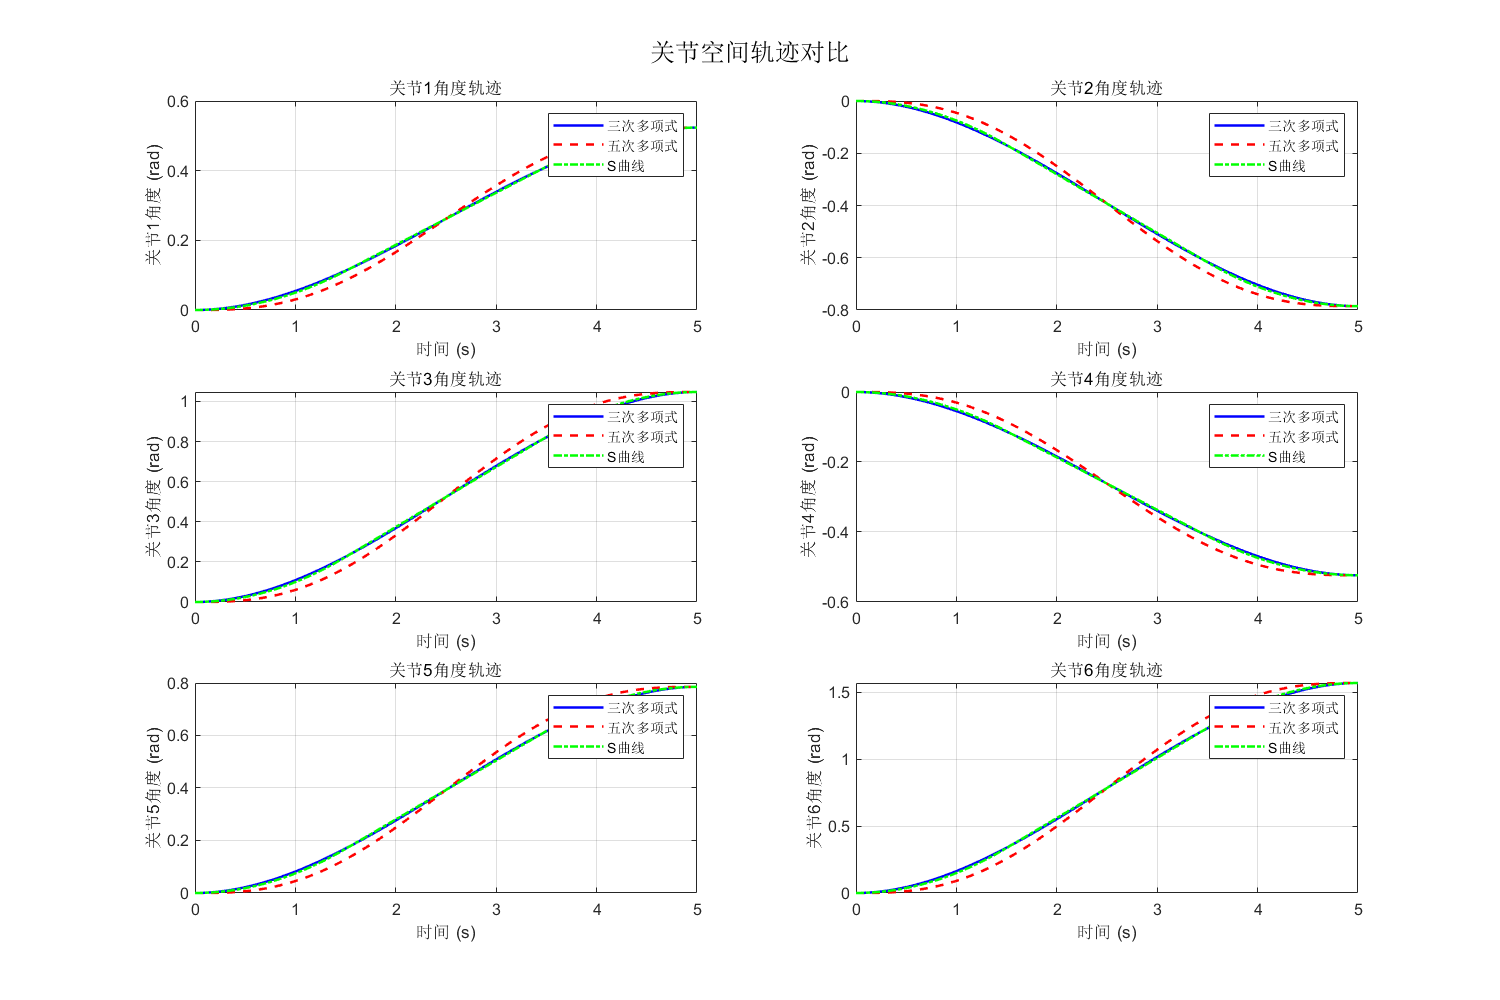

figure('Position', [100, 100, 1200, 800]);
sgtitle('关节空间轨迹对比');

for i = 1:n
    subplot(3, 2, i);
    plot(t, q_cubic(:,i), 'b-', 'LineWidth', 1.5); hold on;
    plot(t, q_quintic(:,i), 'r--', 'LineWidth', 1.5);
    plot(t, q_s_curve(:,i), 'g-.', 'LineWidth', 1.5);
    xlabel('时间 (s)');
    ylabel(['关节', num2str(i), '角度 (rad)']);
    title(['关节', num2str(i), '角度轨迹']);
    legend('三次多项式', '五次多项式', 'S曲线');
    grid on;
end

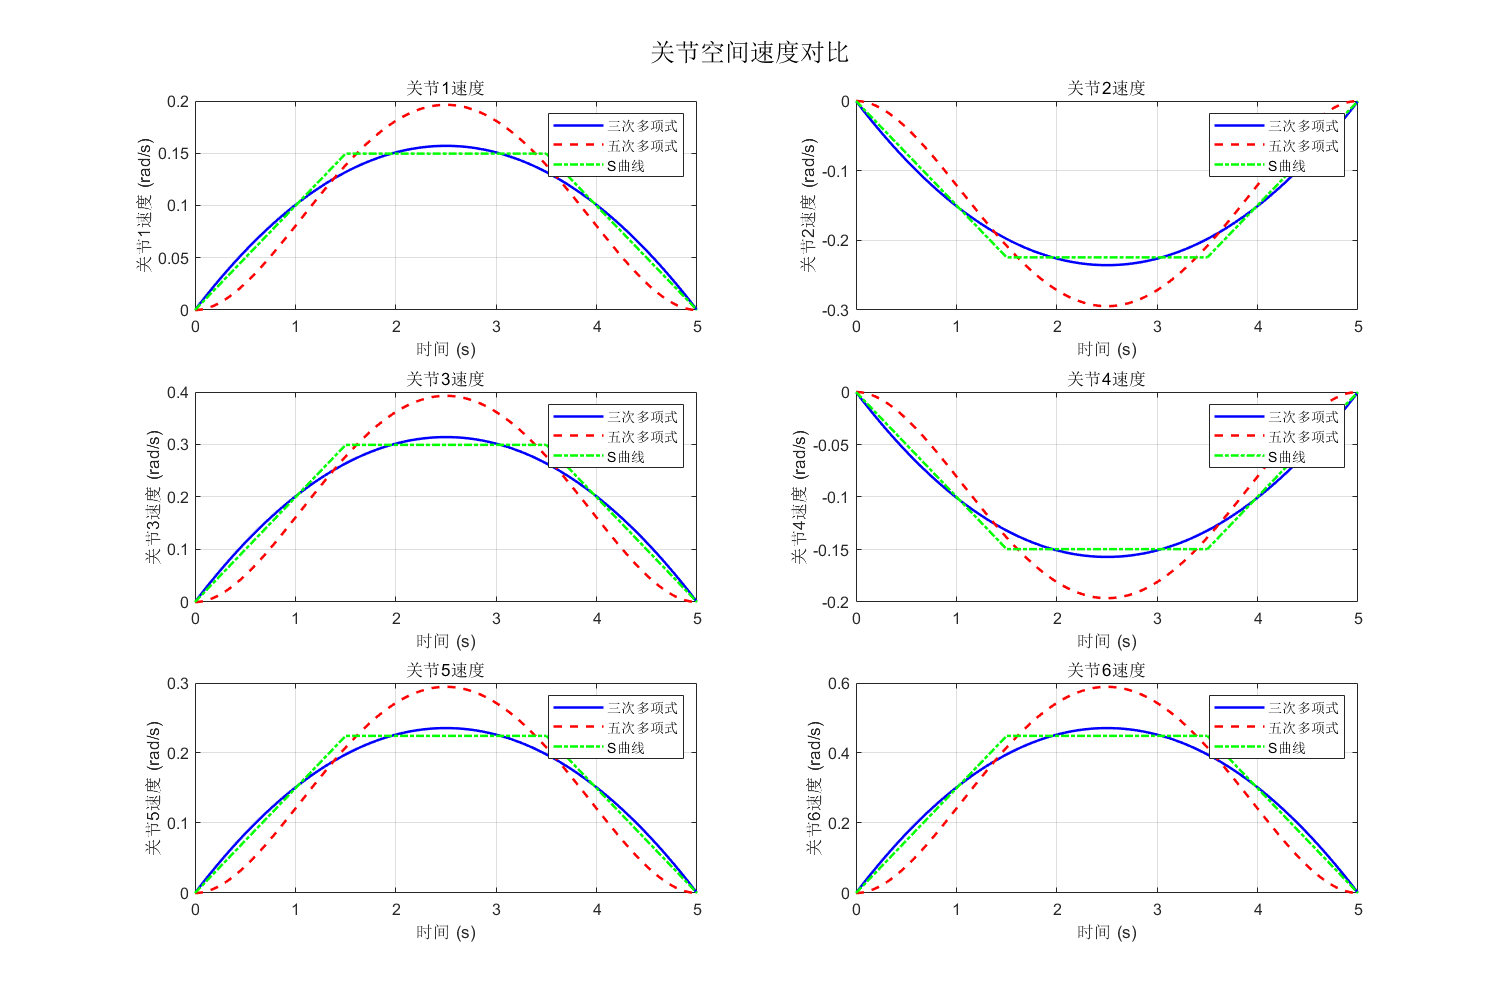


% 2. 关节空间速度对比
figure('Position', [100, 100, 1200, 800]);
sgtitle('关节空间速度对比');

for i = 1:n
    subplot(3, 2, i);
    plot(t, dq_cubic(:,i), 'b-', 'LineWidth', 1.5); hold on;
    plot(t, dq_quintic(:,i), 'r--', 'LineWidth', 1.5);
    plot(t, dq_s_curve(:,i), 'g-.', 'LineWidth', 1.5);
    xlabel('时间 (s)');
    ylabel(['关节', num2str(i), '速度 (rad/s)']);
    title(['关节', num2str(i), '速度']);
    legend('三次多项式', '五次多项式', 'S曲线');
    grid on;
end

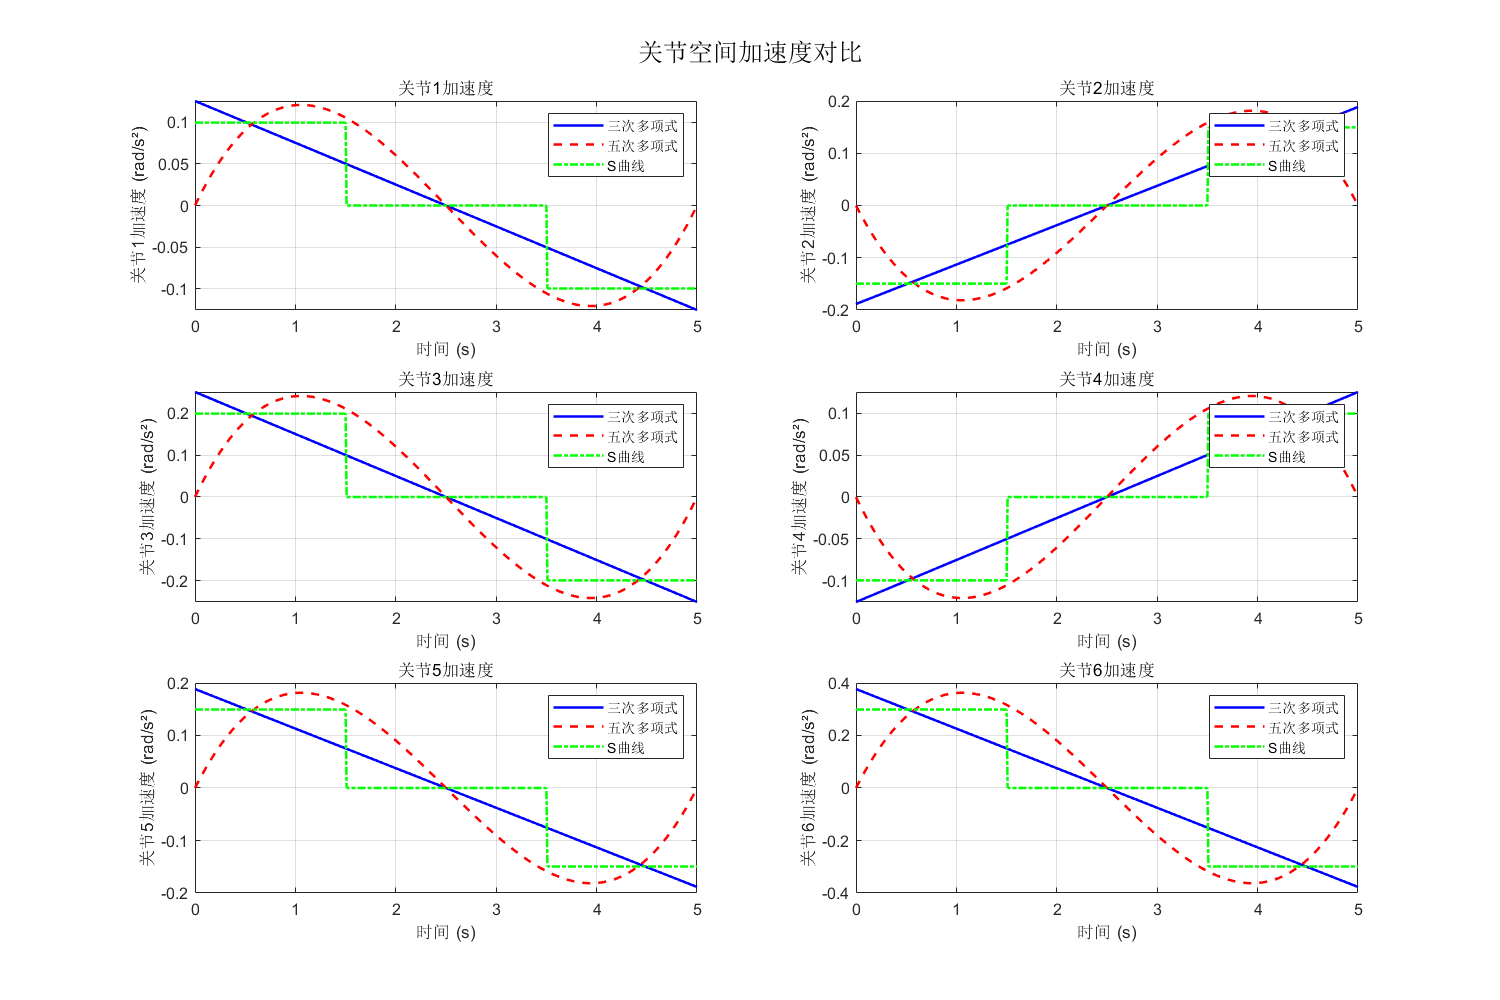


% 3. 关节空间加速度对比
figure('Position', [100, 100, 1200, 800]);
sgtitle('关节空间加速度对比');

for i = 1:n
    subplot(3, 2, i);
    plot(t, ddq_cubic(:,i), 'b-', 'LineWidth', 1.5); hold on;
    plot(t, ddq_quintic(:,i), 'r--', 'LineWidth', 1.5);
    plot(t, ddq_s_curve(:,i), 'g-.', 'LineWidth', 1.5);
    xlabel('时间 (s)');
    ylabel(['关节', num2str(i), '加速度 (rad/s²)']);
    title(['关节', num2str(i), '加速度']);
    legend('三次多项式', '五次多项式', 'S曲线');
    grid on;
end

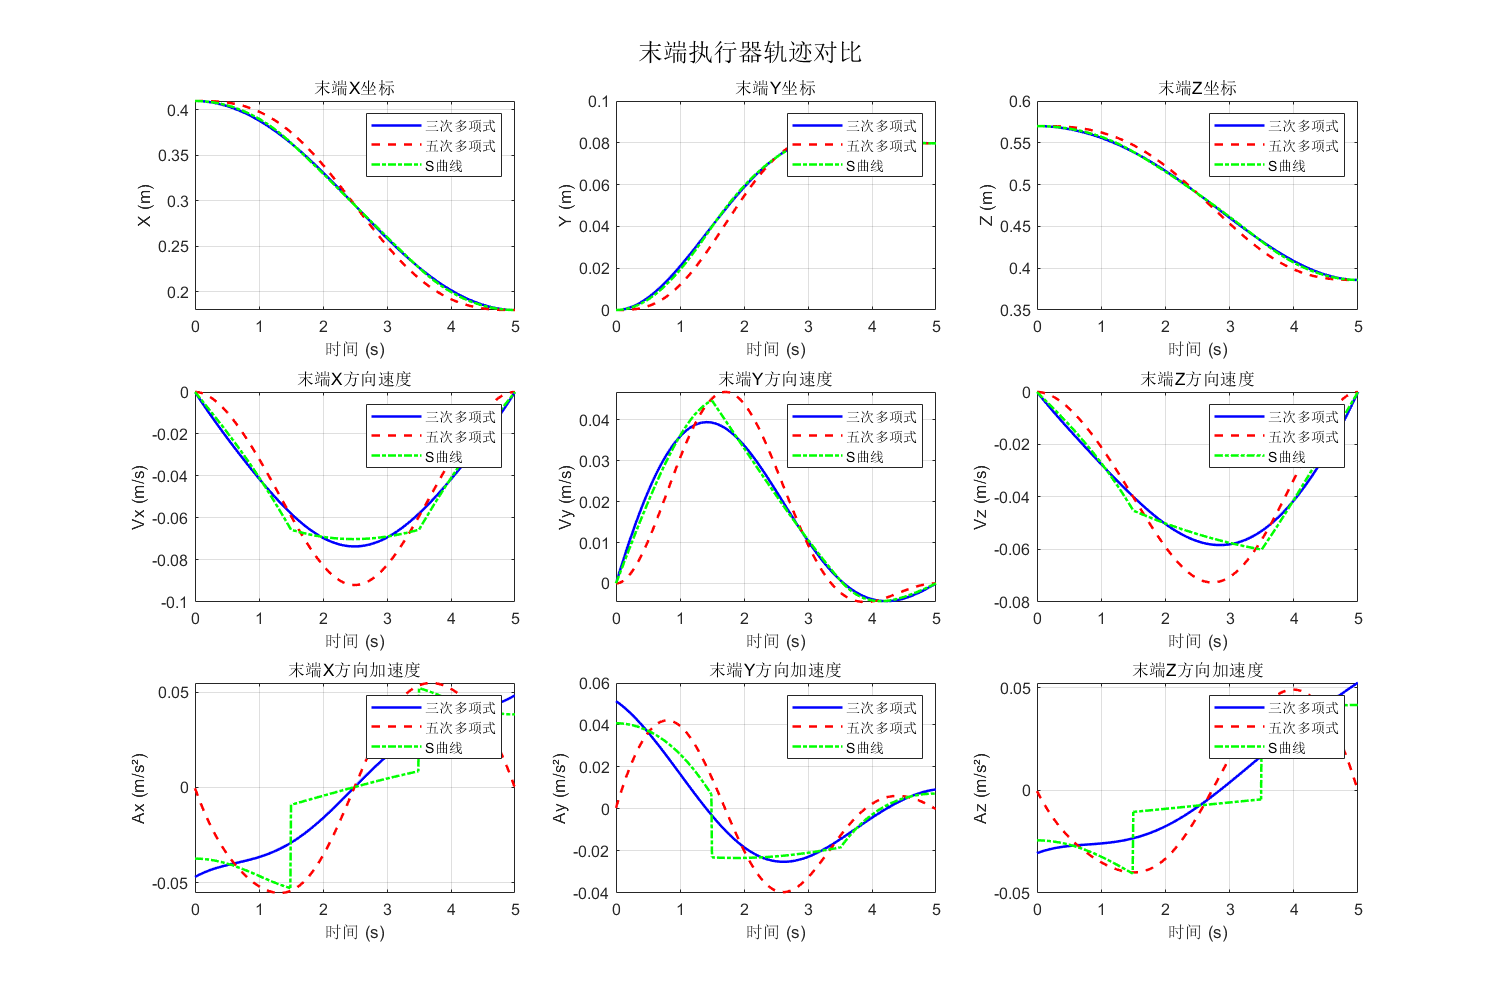


% 4. 末端执行器轨迹对比
figure('Position', [100, 100, 1200, 800]);
sgtitle('末端执行器轨迹对比');

% 位置对比
subplot(3, 3, 1);
plot(t, pos_cubic(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(t, pos_quintic(:,1), 'r--', 'LineWidth', 1.5);
plot(t, pos_s_curve(:,1), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('X (m)');
title('末端X坐标');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 2);
plot(t, pos_cubic(:,2), 'b-', 'LineWidth', 1.5); hold on;
plot(t, pos_quintic(:,2), 'r--', 'LineWidth', 1.5);
plot(t, pos_s_curve(:,2), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Y (m)');
title('末端Y坐标');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 3);
plot(t, pos_cubic(:,3), 'b-', 'LineWidth', 1.5); hold on;
plot(t, pos_quintic(:,3), 'r--', 'LineWidth', 1.5);
plot(t, pos_s_curve(:,3), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Z (m)');
title('末端Z坐标');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

% 速度对比
subplot(3, 3, 4);
plot(t, vel_cubic(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(t, vel_quintic(:,1), 'r--', 'LineWidth', 1.5);
plot(t, vel_s_curve(:,1), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Vx (m/s)');
title('末端X方向速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 5);
plot(t, vel_cubic(:,2), 'b-', 'LineWidth', 1.5); hold on;
plot(t, vel_quintic(:,2), 'r--', 'LineWidth', 1.5);
plot(t, vel_s_curve(:,2), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Vy (m/s)');
title('末端Y方向速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 6);
plot(t, vel_cubic(:,3), 'b-', 'LineWidth', 1.5); hold on;
plot(t, vel_quintic(:,3), 'r--', 'LineWidth', 1.5);
plot(t, vel_s_curve(:,3), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Vz (m/s)');
title('末端Z方向速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

% 加速度对比
subplot(3, 3, 7);
plot(t, acc_cubic(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(t, acc_quintic(:,1), 'r--', 'LineWidth', 1.5);
plot(t, acc_s_curve(:,1), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Ax (m/s²)');
title('末端X方向加速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 8);
plot(t, acc_cubic(:,2), 'b-', 'LineWidth', 1.5); hold on;
plot(t, acc_quintic(:,2), 'r--', 'LineWidth', 1.5);
plot(t, acc_s_curve(:,2), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Ay (m/s²)');
title('末端Y方向加速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

subplot(3, 3, 9);
plot(t, acc_cubic(:,3), 'b-', 'LineWidth', 1.5); hold on;
plot(t, acc_quintic(:,3), 'r--', 'LineWidth', 1.5);
plot(t, acc_s_curve(:,3), 'g-.', 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('Az (m/s²)');
title('末端Z方向加速度');
legend('三次多项式', '五次多项式', 'S曲线');
grid on;

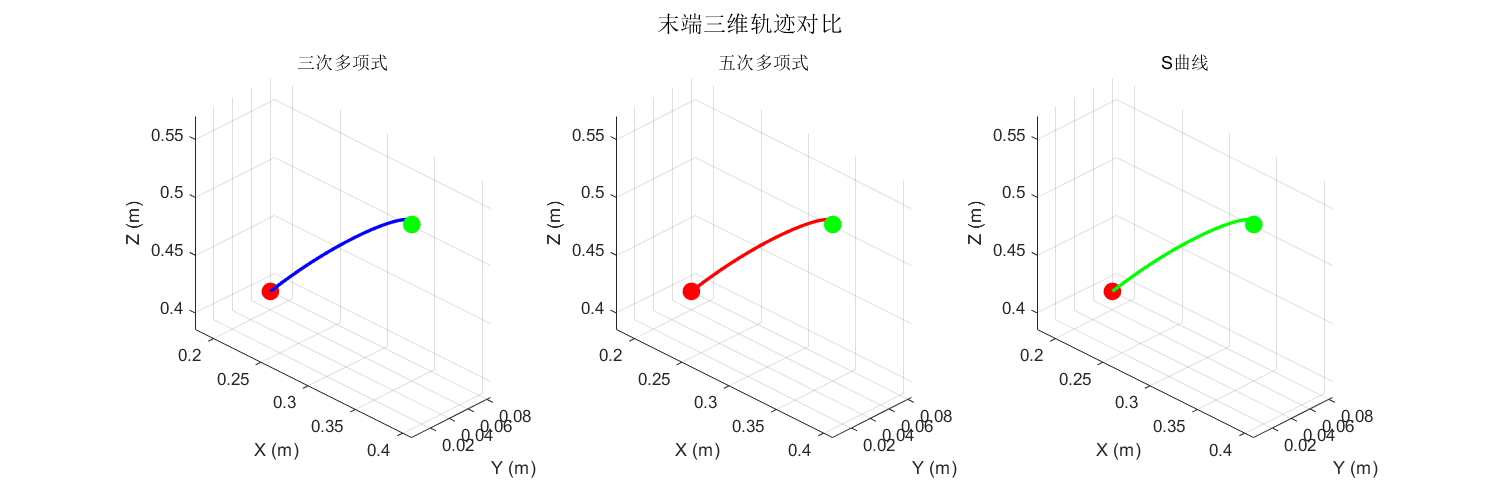


% 5. 三维轨迹可视化
figure('Position', [100, 100, 1200, 400]);
sgtitle('末端三维轨迹对比');

subplot(1, 3, 1);
plot3(pos_cubic(:,1), pos_cubic(:,2), pos_cubic(:,3), 'b-', 'LineWidth', 2);
hold on;
% 绘制起始和结束点
plot3(pos_cubic(1,1), pos_cubic(1,2), pos_cubic(1,3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(pos_cubic(end,1), pos_cubic(end,2), pos_cubic(end,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('三次多项式');
grid on; axis equal;
view(45, 30);

subplot(1, 3, 2);
plot3(pos_quintic(:,1), pos_quintic(:,2), pos_quintic(:,3), 'r-', 'LineWidth', 2);
hold on;
plot3(pos_quintic(1,1), pos_quintic(1,2), pos_quintic(1,3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(pos_quintic(end,1), pos_quintic(end,2), pos_quintic(end,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('五次多项式');
grid on; axis equal;
view(45, 30);

subplot(1, 3, 3);
plot3(pos_s_curve(:,1), pos_s_curve(:,2), pos_s_curve(:,3), 'g-', 'LineWidth', 2);
hold on;
plot3(pos_s_curve(1,1), pos_s_curve(1,2), pos_s_curve(1,3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(pos_s_curve(end,1), pos_s_curve(end,2), pos_s_curve(end,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('S曲线');
grid on; axis equal;
view(45, 30);

## 打印统计信息

fprintf('========== 轨迹规划结果对比 ==========\n');

========== 轨迹规划结果对比 ==========


fprintf('总运动时间: %.2f 秒\n', t_total);

总运动时间: 5.00 秒


fprintf('轨迹点数: %d\n', N);

轨迹点数: 501


fprintf('\n');

% 计算最大速度、加速度和加加速度
fprintf('三次多项式:\n');

三次多项式:


fprintf('  最大关节速度: %.4f rad/s\n', max(abs(dq_cubic(:))));

  最大关节速度: 0.4712 rad/s


fprintf('  最大关节加速度: %.4f rad/s²\n', max(abs(ddq_cubic(:))));

  最大关节加速度: 0.3770 rad/s²


fprintf('  末端最大速度: %.4f m/s\n', max(sqrt(sum(vel_cubic.^2, 2))));

  末端最大速度: 0.0957 m/s



fprintf('\n五次多项式:\n');


五次多项式:


fprintf('  最大关节速度: %.4f rad/s\n', max(abs(dq_quintic(:))));

  最大关节速度: 0.5890 rad/s


fprintf('  最大关节加速度: %.4f rad/s²\n', max(abs(ddq_quintic(:))));

  最大关节加速度: 0.3628 rad/s²


fprintf('  末端最大速度: %.4f m/s\n', max(sqrt(sum(vel_quintic.^2, 2))));

  末端最大速度: 0.1196 m/s



fprintf('\nS曲线:\n');


S曲线:


fprintf('  最大关节速度: %.4f rad/s\n', max(abs(dq_s_curve(:))));

  最大关节速度: 0.4488 rad/s


fprintf('  最大关节加速度: %.4f rad/s²\n', max(abs(ddq_s_curve(:))));

  最大关节加速度: 0.2992 rad/s²


fprintf('  末端最大速度: %.4f m/s\n', max(sqrt(sum(vel_s_curve.^2, 2))));

  末端最大速度: 0.0914 m/s
